# **Extended Kalman Filter (BFT)**

**In this code I will create a kalman filter that uses 2 camera's to track a 3 features on a body frame moving around a 3D space. (Body frame tracking)**

Step 1: New predicted state

syms Px Py Pz Vx Vy Vz Ax Ay Az q0 qx qy qz theta_x theta_y theta_z omega_x omega_y omega_z alpha_x alpha_y alpha_z dT

%Calculation of A matrix
assume(dT,'real')

x_t = Px + Vx*dT + 1/2*Ax*dT^2

$$x\_t = \frac{\text{Ax}\,{\mathrm{dT}}^{2}}{2}+\mathrm{Vx}\,\mathrm{dT}+\mathrm{Px}$$

dx_t = diff(x_t,dT);
y_t = Py + Vy*dT + 1/2*Ay*dT^2;
dy_t = diff(y_t,dT);
z_t = Pz + Vz*dT + 1/2*Az*dT^2;
dz_t = diff(z_t,dT);

quat = [q0;qx;qy;qz];
assume(quat,'real')
qI = sym([1;0;0;0]);
omega = [0;omega_x;omega_y;omega_z];
assume(omega,'real')

q_t = quatmultiply(quat', (qI+dT/2*omega)');
theta_x_t = theta_x + omega_x*dT + 1/2*alpha_x*dT^2;
omega_x_t = diff(theta_x_t,dT);
theta_y_t = theta_y + omega_y*dT + 1/2*alpha_y*dT^2;
omega_y_t = diff(theta_y_t,dT);
theta_z_t = theta_z + omega_z*dT + 1/2*alpha_z*dT^2;
omega_z_t = diff(theta_z_t,dT);

X_k = [Px Py Pz Vx Vy Vz q0 qx qy qz omega_x omega_y omega_z].';
kinematics = [x_t y_t z_t dx_t dy_t dz_t q_t omega_x_t omega_y_t omega_z_t];
A = sym('A%d%d',[13 13]);
for i = 1:length(kinematics)
    for k = 1: length(X_k) 
        A(i,k) = diff(kinematics(i),X_k(k));
    end
end
A_x = A

$$A\_x = \begin{array}{l} \left(\begin{array}{ccccccccccccc} 1 & 0 & 0 & \mathrm{dT} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & \mathrm{dT} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & \mathrm{dT} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & \sigma_{6} & \sigma_{5} & \sigma_{4} & \sigma_{3} & \sigma_{2} & \sigma_{1}\\ 0 & 0 & 0 & 0 & 0 & 0 & \frac{\mathrm{dT}\,\omega_{x}}{2} & 1 & \frac{\mathrm{dT}\,\omega_{z}}{2} & \sigma_{5} & \frac{\mathrm{dT}\,q_{0}}{2} & \sigma_{1} & \frac{\mathrm{dT}\,\mathrm{qy}}{2}\\ 0 & 0 & 0 & 0 & 0 & 0 & \frac{\mathrm{dT}\,\omega_{y}}{2} & \sigma_{4} & 1 & \frac{\mathrm{dT}\,\omega_{x}}{2} & \frac{\mathrm{dT}\,\mathrm{qz}}{2} & \frac{\mathrm{dT}\,q_{0}}{2} & \sigma_{3}\\ 0 & 0 & 0 & 0 & 0 & 0 & \frac{\mathrm{dT}\,\omega_{z}}{2} & \frac{\mathrm{dT}\,\omega_{y}}{2} & \sigma_{6} & 1 & \sigma_{2} & \frac{\mathrm{dT}\,\mathrm{qx}}{2} & \frac{\mathrm{dT}\,q_{0}}{2}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\mathrm{dT}\,\mathrm{qz}}{2}\\ \sigma_{2}=-\frac{\mathrm{dT}\,\mathrm{qy}}{2}\\ \sigma_{3}=-\frac{\mathrm{dT}\,\mathrm{qx}}{2}\\ \sigma_{4}=-\frac{\mathrm{dT}\,\omega_{z}}{2}\\ \sigma_{5}=-\frac{\mathrm{dT}\,\omega_{y}}{2}\\ \sigma_{6}=-\frac{\mathrm{dT}\,\omega_{x}}{2} \end{array}$$

A_x(7:10,7:10) = eye(4)

$$A\_x = \begin{array}{l} \left(\begin{array}{ccccccccccccc} 1 & 0 & 0 & \mathrm{dT} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & \mathrm{dT} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & \mathrm{dT} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & \sigma_{3} & \sigma_{2} & \sigma_{1}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0 & \frac{\mathrm{dT}\,q_{0}}{2} & \sigma_{1} & \frac{\mathrm{dT}\,\mathrm{qy}}{2}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & \frac{\mathrm{dT}\,\mathrm{qz}}{2} & \frac{\mathrm{dT}\,q_{0}}{2} & \sigma_{3}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & \sigma_{2} & \frac{\mathrm{dT}\,\mathrm{qx}}{2} & \frac{\mathrm{dT}\,q_{0}}{2}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\mathrm{dT}\,\mathrm{qz}}{2}\\ \sigma_{2}=-\frac{\mathrm{dT}\,\mathrm{qy}}{2}\\ \sigma_{3}=-\frac{\mathrm{dT}\,\mathrm{qx}}{2} \end{array}$$

% A_x(7,8:10)=0;
% A_x(8,7)=0;
% A_x(8,9:10)=0;
% A_x(9,7:8)=0;
% A_x(9,10)=0;
% A_x(10,7:9)=0;
%calculation of B matrix
U_k = [Ax Ay Az alpha_x alpha_y alpha_z].';
B = sym('B%d%d',[13 6]);
for i = 1:length(kinematics)
    for k = 1: length(U_k) 
        B(i,k) = diff(kinematics(i),U_k(k));
    end
end

%Calc of Xkp
X_kp = A_x*X_k

$$X\_kp = \left(\begin{array}{c} \mathrm{Px}+\mathrm{Vx}\,\mathrm{dT}\\ \mathrm{Py}+\mathrm{Vy}\,\mathrm{dT}\\ \mathrm{Pz}+\mathrm{Vz}\,\mathrm{dT}\\ \mathrm{Vx}\\ \mathrm{Vy}\\ \mathrm{Vz}\\ q_{0}-\frac{\mathrm{dT}\,\omega_{x}\,\mathrm{qx}}{2}-\frac{\mathrm{dT}\,\omega_{y}\,\mathrm{qy}}{2}-\frac{\mathrm{dT}\,\omega_{z}\,\mathrm{qz}}{2}\\ \mathrm{qx}+\frac{\mathrm{dT}\,\omega_{x}\,q_{0}}{2}+\frac{\mathrm{dT}\,\omega_{z}\,\mathrm{qy}}{2}-\frac{\mathrm{dT}\,\omega_{y}\,\mathrm{qz}}{2}\\ \mathrm{qy}+\frac{\mathrm{dT}\,\omega_{y}\,q_{0}}{2}-\frac{\mathrm{dT}\,\omega_{z}\,\mathrm{qx}}{2}+\frac{\mathrm{dT}\,\omega_{x}\,\mathrm{qz}}{2}\\ \mathrm{qz}+\frac{\mathrm{dT}\,\omega_{z}\,q_{0}}{2}+\frac{\mathrm{dT}\,\omega_{y}\,\mathrm{qx}}{2}-\frac{\mathrm{dT}\,\omega_{x}\,\mathrm{qy}}{2}\\ \omega_{x}\\ \omega_{y}\\ \omega_{z} \end{array}\right)$$

Step 2: Select P Matrix and find Pkp

syms ePx ePy ePz eVx eVy eVz eAx eAy eAz eq0 eqx eqy eqz eomega_x eomega_y eomega_z ealpha_x ealpha_y ealpha_z
errors = [ePx ePy ePz eVx eVy eVz eq0 eqx eqy eqz eomega_x eomega_y eomega_z];
P = sym(zeros(length(errors)));
for i=1:length(errors)
    P(i,i)=errors(i)*errors(i);
end
P

$$P = \left(\begin{array}{ccccccccccccc} {\mathrm{ePx}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{ePy}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & {\mathrm{ePz}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & {\mathrm{eVx}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & {\mathrm{eVy}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & {\mathrm{eVz}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eq}}_{0}}^{2} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & {\mathrm{eqx}}^{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {\mathrm{eqy}}^{2} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {\mathrm{eqz}}^{2} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eomega}}_{x}}^{2} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eomega}}_{y}}^{2} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eomega}}_{z}}^{2} \end{array}\right)$$

errors = [eAx eAy eAz ealpha_x ealpha_y ealpha_z];
Q = sym(zeros(length(errors)));
for i=1:length(errors)
    Q(i,i)=errors(i)*errors(i);
end

G = B;
G(1:3,:)=0

$$G = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ \mathrm{dT} & 0 & 0 & 0 & 0 & 0\\ 0 & \mathrm{dT} & 0 & 0 & 0 & 0\\ 0 & 0 & \mathrm{dT} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \mathrm{dT} & 0 & 0\\ 0 & 0 & 0 & 0 & \mathrm{dT} & 0\\ 0 & 0 & 0 & 0 & 0 & \mathrm{dT} \end{array}\right)$$

G

$$G = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ \mathrm{dT} & 0 & 0 & 0 & 0 & 0\\ 0 & \mathrm{dT} & 0 & 0 & 0 & 0\\ 0 & 0 & \mathrm{dT} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \mathrm{dT} & 0 & 0\\ 0 & 0 & 0 & 0 & \mathrm{dT} & 0\\ 0 & 0 & 0 & 0 & 0 & \mathrm{dT} \end{array}\right)$$

Q

$$Q = \left(\begin{array}{cccccc} {\mathrm{eAx}}^{2} & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{eAy}}^{2} & 0 & 0 & 0 & 0\\ 0 & 0 & {\mathrm{eAz}}^{2} & 0 & 0 & 0\\ 0 & 0 & 0 & {{\mathrm{ealpha}}_{x}}^{2} & 0 & 0\\ 0 & 0 & 0 & 0 & {{\mathrm{ealpha}}_{y}}^{2} & 0\\ 0 & 0 & 0 & 0 & 0 & {{\mathrm{ealpha}}_{z}}^{2} \end{array}\right)$$

Q_k = G*Q*G.';
Pkp = A*P*A.' + Q_k

Step 4: Calc KG

syms Pu Pv u0 v0 f 

%camera intrinsic values
Kp = [1/Pu 0 u0;
    0 1/Pv v0;
    0 0 1];
Kf = [f 0 0 0;
      0 f 0 0;
      0 0 1 0];
K = Kp*Kf;

%camera matrix
C1 = sym('C%d%d_1', [3 4]);
C2 = sym('C%d%d_2', [3 4]);

%feature location wrt body frame
f2b_1 = sym('f2b_1_%d',[3 1]);
f2b_2 = sym('f2b_2_%d',[3 1]);
f2b_3 = sym('f2b_3_%d',[3 1]);

%quaternion rotation matrix
R_w2b = [2*(q0^2+qx^2)-1 2*(qx*qy - q0*qz) 2*(qx*qz + q0*qy);
         2*(qx*qy+q0*qz) 2*(q0^2+qy^2)-1 2*(qy*qz + q0+qy);
         2*(qx*qz-q0*qy) 2*(qy*qz+q0*qx) 2*(q0^2+qz^2)-1];

%Position of body frame
w_p = [Px Py Pz].';

%Camera 1 UV
UV_1 = C1*[w_p+R_w2b*f2b_1;1];
UV_1 = UV_1/UV_1(3);
UV_2 = C1*[w_p+R_w2b*f2b_2;1];
UV_2 = UV_2/UV_2(3);
UV_3 = C1*[w_p+R_w2b*f2b_3;1];
UV_3 = UV_3/UV_3(3);

U1_1 = UV_1(1);
V1_1 = UV_1(2);
U1_2 = UV_2(1);
V1_2 = UV_2(2);
U1_3 = UV_3(1);
V1_3 = UV_3(2);

%Camera 2 UV
UV_1 = C2*[w_p+R_w2b*f2b_1;1];
UV_1 = UV_1/UV_1(3);
UV_2 = C2*[w_p+R_w2b*f2b_2;1];
UV_2 = UV_2/UV_2(3);
UV_3 = C2*[w_p+R_w2b*f2b_3;1];
UV_3 = UV_3/UV_3(3);

U2_1 = UV_1(1);
V2_1 = UV_1(2);
U2_2 = UV_2(1);
V2_2 = UV_2(2);
U2_3 = UV_3(1);
V2_3 = UV_3(2);

%H Calc
observations = [U1_1 V1_1 U1_2 V1_2 U1_3 V1_3 U2_1 V2_1 U2_2 V2_2 U2_3 V2_3];
H = sym('H%d%d',[length(observations) length(X_k)]);
for i = 1:length(observations)
    for k = 1: length(X_k)
        H(i,k) = diff(observations(i),X_k(k));
    end
end
size(H)

ans =     12    13


H

%R calc symbols
syms eU1_1 eV1_1 eU1_2 eV1_2 eU1_3 eV1_3 eU2_1 eV2_1 eU2_2 eV2_2 eU2_3 eV2_3
errors = [eU1_1 eV1_1 eU1_2 eV1_2 eU1_3 eV1_3 eU2_1 eV2_1 eU2_2 eV2_2 eU2_3 eV2_3];
R = sym(zeros(length(errors)));
for i = 1:length(errors)
        R(i,i) = errors(i)^2;
end
R

$$R = \left(\begin{array}{cccccccccccc} {{\mathrm{eU}}_{1,1}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & {{\mathrm{eV}}_{1,1}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & {{\mathrm{eU}}_{1,2}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & {{\mathrm{eV}}_{1,2}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & {{\mathrm{eU}}_{1,3}}^{2} & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & {{\mathrm{eV}}_{1,3}}^{2} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eU}}_{2,1}}^{2} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eV}}_{2,1}}^{2} & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eU}}_{2,2}}^{2} & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eV}}_{2,2}}^{2} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eU}}_{2,3}}^{2} & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & {{\mathrm{eV}}_{2,3}}^{2} \end{array}\right)$$

EKF Values:

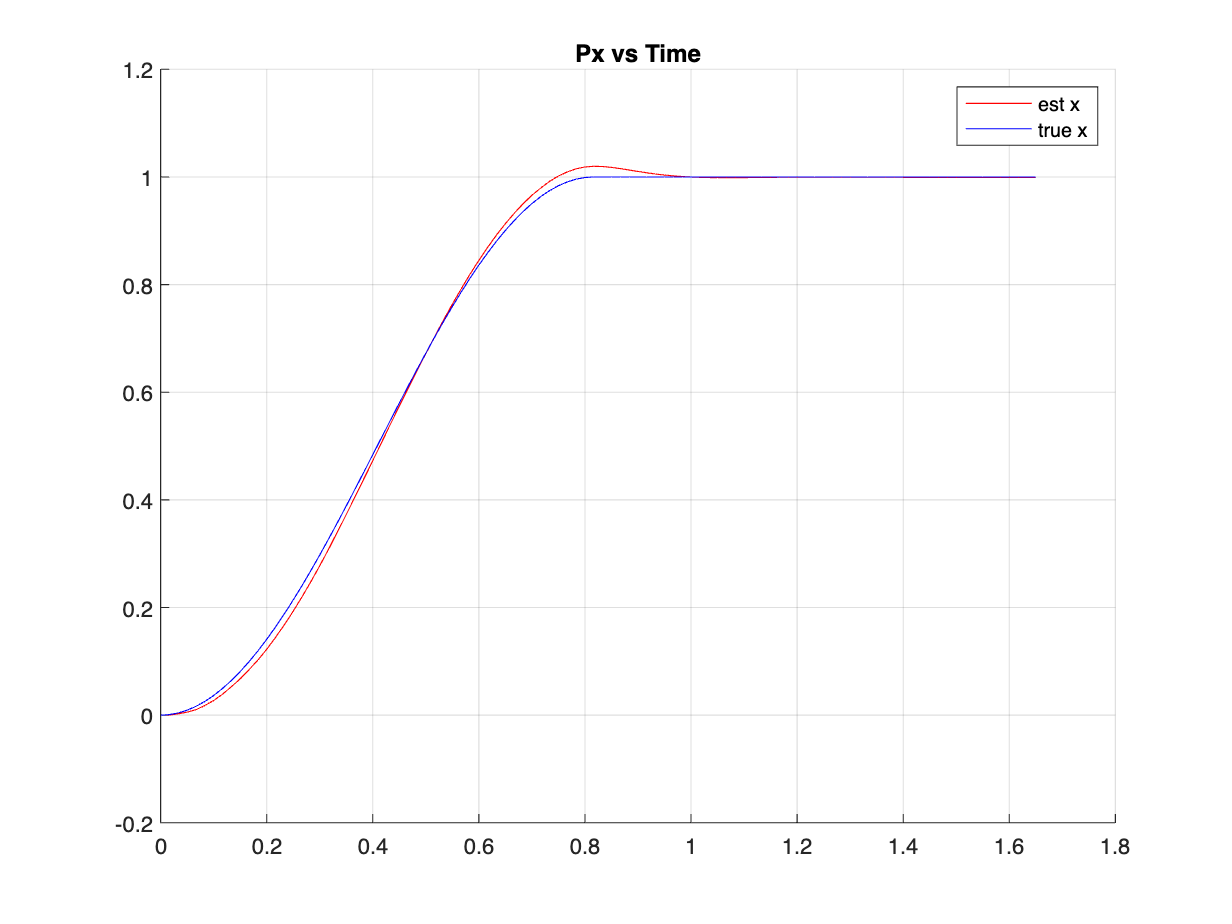

%initial conditions
Px = 0;
Py = 0;
Pz = 0;
Vx = 0;
Vy = 0;
Vz = 0;
Ax = 0;
Ay = 0;
Az = 0;
q0 = 1;
qx = 0;
qy = 0;
qz = 0;
omega_x = 0;
omega_y = 0;
omega_z = 0;
alpha_x = 0;
alpha_y = 0;
alpha_z = 0;
dT = 1/60;

%eInitial conditions
ePx = 0.1;
ePy = 0.1;
ePz = 0.1;
eVx = 0.01;
eVy = 0.01;
eVz = 0.01;
eq0 = 0.1;
eqx = 0.1;
eqy = 0.1;
eqz = 0.1;
eomega_x = 0.01;
eomega_y = 0.01;
eomega_z = 0.01;

%Qk creation (uniform distribution)
Amax = 20*0.01;
eAx = sqrt((Amax-(-Amax))^2/12);
eAy = sqrt((Amax-(-Amax))^2/12);
eAz = sqrt((Amax-(-Amax))^2/12);
alphaMax = 5*0.1;
ealpha_x = sqrt((alphaMax-(-alphaMax))^2/12);
ealpha_y = sqrt((alphaMax-(-alphaMax))^2/12);
ealpha_z = sqrt((alphaMax-(-alphaMax))^2/12);

%camera model intrisic & extrinsic parameters
f = 0.008;
Pu = 10e-6;
Pv = 10e-6;
u0 = 360;
v0 = 240;
Kf_ = eval(Kf);
Kp_ =  eval(Kp);
K_ = eval(K);
% r_c1 = roty(120);
% t_c1 = [-4;0;3];
% T_c2w1 = [r_c1 t_c1;
%             0 0 0 1];
% invT_c2w1 = inv(T_c2w1);
invT_c2w1 = eye(4)/[cos(deg2rad(120)) 0 sin(deg2rad(120)) -4; 0 1 0 0; -sin(deg2rad(120)) 0 cos(deg2rad(120)) 3; 0 0 0 1];
C1_ = K_*invT_c2w1;
% r_c2 = rotx(120);
% t_c2 = [0;4;3];
% T_c2w2 = [r_c2 t_c2;
%          0 0 0 1];
% invT_c2w2 = inv(T_c2w2);
invT_c2w2 = eye(4)/[1 0 0 0; 0 cos(deg2rad(120)) -sin(deg2rad(120)) 4; 0 sin(deg2rad(120)) cos(deg2rad(120)) 3; 0 0 0 1];
C2_ = K_*invT_c2w2;

%body parameters
f1 = [0.25 0 0]';
f2 = [0 0.25 0]';
f3 = [0 -0.25 0]';

%H matrix constants subs
H__ = subs(H,C1,C1_);
H__ = subs(H__,C2,C2_);
H__ = subs(H__,f2b_1,f1);
H__ = subs(H__,f2b_2,f2);
H__ = subs(H__,f2b_3,f3);

%R matrix calculations
maxError_p = (sqrt(1+1)/2);
eU1_1 = sqrt((maxError_p)^2/12);
eV1_1 = sqrt((maxError_p)^2/12);
eU1_2 = sqrt((maxError_p)^2/12);
eV1_2 = sqrt((maxError_p)^2/12);
eU1_3 = sqrt((maxError_p)^2/12);
eV1_3 = sqrt((maxError_p)^2/12);
eU2_1 = sqrt((maxError_p)^2/12);
eV2_1 = sqrt((maxError_p)^2/12);
eU2_2 = sqrt((maxError_p)^2/12);
eV2_2 = sqrt((maxError_p)^2/12);
eU2_3 = sqrt((maxError_p)^2/12);
eV2_3 = sqrt((maxError_p)^2/12);
R_ = eval(R);

%camera model for estimation
kp_x = [Kp_ zeros(3,15); 
        zeros(3) Kp_ zeros(3,12); 
        zeros(3,6) Kp_ zeros(3,9); 
        zeros(3,9) Kp_ zeros(3,6);
        zeros(3,12) Kp_ zeros(3);
        zeros(3,15) Kp_];
kf_x = [Kf_ zeros(3,20); 
        zeros(3,4) Kf_ zeros(3,16);
        zeros(3,8) Kf_ zeros(3,12);
        zeros(3,12) Kf_ zeros(3,8);
        zeros(3,16) Kf_ zeros(3,4);
        zeros(3,20) Kf_];
invc2w_x = [invT_c2w1 zeros(4,8);
            zeros(4) invT_c2w1 zeros(4);
            zeros(4,8) invT_c2w1;
            invT_c2w2 zeros(4,8);
            zeros(4) invT_c2w2 zeros(4);
            zeros(4,8) invT_c2w2];
c_x = kp_x*kf_x*invc2w_x;


%calculating pixel start and end points with respect to resolution
n_iterations = 100;
n_uv=50;
%x true
x_t = linspace(-pi/2,pi/2,n_uv);
x_movement = (1)*(sin(x_t)+1)/2;
x_rest = x_movement(n_uv).*ones(1,n_iterations-n_uv);
x_true = [x_movement x_rest];
%y true
y_t = linspace(-pi/2,pi/2,n_uv);
y_movement = (1)*(sin(y_t)+1)/2;
y_rest = y_movement(n_uv).*ones(1,n_iterations-n_uv);
y_true = [y_movement y_rest];
%z true
z_t = linspace(-pi/2,pi/2,n_uv);
z_movement = (1)*(sin(z_t)+1)/2;
z_rest = z_movement(n_uv).*ones(1,n_iterations-n_uv);
z_true = [z_movement z_rest];
%phi true
phi_t = linspace(-pi/2,pi/2,n_uv);
phi_movement = (1/2)*(sin(phi_t)+1)/2;
phi_rest = phi_movement(n_uv).*ones(1,n_iterations-n_uv);
phi_true = [phi_movement phi_rest];
%theta true
theta_t = linspace(-pi/2,pi/2,n_uv);
theta_movement = (1/2)*(sin(theta_t)+1)/2;
theta_rest = theta_movement(n_uv).*ones(1,n_iterations-n_uv);
theta_true = [theta_movement theta_rest];
%psi true
psi_t = linspace(-pi/2,pi/2,n_uv);
psi_movement = (1/2)*(sin(psi_t)+1)/2;
psi_rest = psi_movement(n_uv).*ones(1,n_iterations-n_uv);
psi_true = [psi_movement psi_rest];
%true position & orientation
true_position = zeros(3,n_iterations);
quat_true = zeros(n_iterations,4);
loc_f1_w = zeros(4,n_iterations);
loc_f2_w = zeros(4,n_iterations);
loc_f3_w = zeros(4,n_iterations);
eul_true = [phi_true ;theta_true ;psi_true];
for k=1:n_iterations
    true_position(:,k) = [x_true(k) y_true(k) z_true(k)]';
    quat_true(k,:) = eul2quat([phi_true(k) theta_true(k) psi_true(k)]);
    loc_f1_w(:,k) = [true_position(:,k) + quat2rotm(quat_true(k,:))*f1; 1];
    loc_f2_w(:,k) = [true_position(:,k) + quat2rotm(quat_true(k,:))*f2; 1];
    loc_f3_w(:,k) = [true_position(:,k) + quat2rotm(quat_true(k,:))*f3; 1];
end
% for k=1:n_iterations
%     loc_f1_w(:,k) = [true_position(:,k) + quat2rotm(quat_true(k,:))*f1; 1];
%     loc_f2_w(:,k) = [true_position(:,k) + quat2rotm(quat_true(k,:))*f2; 1];
%     loc_f3_w(:,k) = [true_position(:,k) + quat2rotm(quat_true(k,:))*f3; 1];
% end
UVW1_1 = C1_*loc_f1_w;
UVW1_2 = C1_*loc_f2_w;
UVW1_3 = C1_*loc_f3_w;
UVW2_1 = C2_*loc_f1_w;
UVW2_2 = C2_*loc_f2_w;
UVW2_3 = C2_*loc_f3_w;
for k=1:n_iterations
    UVW1_1(:,k) = UVW1_1(:,k)/UVW1_1(3,k);
    UVW1_2(:,k) = UVW1_2(:,k)/UVW1_2(3,k);
    UVW1_3(:,k) = UVW1_3(:,k)/UVW1_3(3,k);
    UVW2_1(:,k) = UVW2_1(:,k)/UVW2_1(3,k);
    UVW2_2(:,k) = UVW2_2(:,k)/UVW2_2(3,k);
    UVW2_3(:,k) = UVW2_3(:,k)/UVW2_3(3,k);
end

UV = round([UVW1_1(1:2,:);UVW1_2(1:2,:);UVW1_3(1:2,:);UVW2_1(1:2,:);UVW2_2(1:2,:);UVW2_3(1:2,:);]);

%number of iterations
x_plot = zeros(n_iterations,1);
y_plot = zeros(n_iterations,1);
z_plot = zeros(n_iterations,1);
Vx_plot = zeros(n_iterations,1);
Vy_plot = zeros(n_iterations,1);
Vz_plot = zeros(n_iterations,1);
eulx_plot = zeros(n_iterations,1);
euly_plot = zeros(n_iterations,1);
eulz_plot = zeros(n_iterations,1);

%initial Pkp and Qk
Pkp_ = eval(Pkp);
Qk_ = eval(Q_k);

%For loop:

for k=1:n_iterations
    %eval X_kp and Pkp
    X_kp_ = eval(X_kp);
    Px = X_kp_(1);
    Py = X_kp_(2);
    Pz = X_kp_(3);
    Vx = X_kp_(4);
    Vy = X_kp_(5);
    Vz = X_kp_(6);
    q0 = X_kp_(7);
    qx = X_kp_(8);
    qy = X_kp_(9);
    qz = X_kp_(10);
    omega_x = X_kp_(11);
    omega_y = X_kp_(12);
    omega_z = X_kp_(13);
    
    %Calc H
    H_ = eval(H__);
    
    %calc KG
    KG = (Pkp_*H_.')/(H_*Pkp_*H_.'+R_);
    
    %observation update
    Zk=UV(:,k);
    
    %h_x*X_kp_ calculation per iteration
    P_f1 = [Px Py Pz]' + eval(R_w2b)*f1;
    P_f2 = [Px Py Pz]' + eval(R_w2b)*f2;
    P_f3 = [Px Py Pz]' + eval(R_w2b)*f3;
    uvw_x = c_x*[P_f1;1;P_f2;1;P_f3;1];
    w_x1_1 = uvw_x(3);
    w_x1_2 = uvw_x(6);
    w_x1_3 = uvw_x(9);
    w_x2_1 = uvw_x(12);
    w_x2_2 = uvw_x(15);
    w_x2_3 = uvw_x(18);
    h_xkp_ = [1/w_x1_1 zeros(1,17);
              0 1/w_x1_1 zeros(1,16);
              zeros(1,3) 1/w_x1_2 zeros(1,14);
              zeros(1,4) 1/w_x1_2 zeros(1,13);
              zeros(1,6) 1/w_x1_3 zeros(1,11);
              zeros(1,7) 1/w_x1_3 zeros(1,10);
              zeros(1,9) 1/w_x2_1 zeros(1,8);
              zeros(1,10) 1/w_x2_1 zeros(1,7);
              zeros(1,12) 1/w_x2_2 zeros(1,5);
              zeros(1,13) 1/w_x2_2 zeros(1,4);
              zeros(1,15) 1/w_x2_3 zeros(1,2);
              zeros(1,16) 1/w_x2_3 0;]*uvw_x;
    
    %current state
    Xk = X_kp_ + KG*(Zk - h_xkp_);
    
    %update Pkp
    Pkp_ = (eye(13)-KG*H_)*Pkp_;
    
    %update states
    Px = Xk(1);
    Py = Xk(2);
    Pz = Xk(3);
    Vx = Xk(4);
    Vy = Xk(5);
    Vz = Xk(6);
    q0 = Xk(7);
    qx = Xk(8);
    qy = Xk(9);
    qz = Xk(10);
    omega_x = Xk(11);
    omega_y = Xk(12);
    omega_z = Xk(13);
    
    %normalise quat
    quat = [q0 qx qy qz];
    normquat = quat/norm(quat);
    q0 = normquat(1);
    qx = normquat(2);
    qy = normquat(3);
    qz = normquat(4);
    
    %Next Pkp_
    A_=eval(A);
    Pkp_ = A_*Pkp_*A_.'+Qk_;
    
    eulZYX = quat2eul([q0 qx qy qz]);
    
    x_plot(k) = Px;
    y_plot(k) = Py;
    z_plot(k) = Pz;
    Vx_plot(k) = Vx;
    Vy_plot(k) = Vy;
    Vz_plot(k) = Vz;
    eulx_plot(k) = eulZYX(1);
    euly_plot(k) = eulZYX(2);
    eulz_plot(k) = eulZYX(3);
end

figure(1),clf,grid,hold on
dI = linspace(0,n_iterations-1,n_iterations);
plot(dT*dI,x_plot,'r-');
plot(dT*dI,true_position(1,:),'b-');
title('Px vs Time')
axis([0 1.8 -0.2 1.2])
legend('est x','true x')

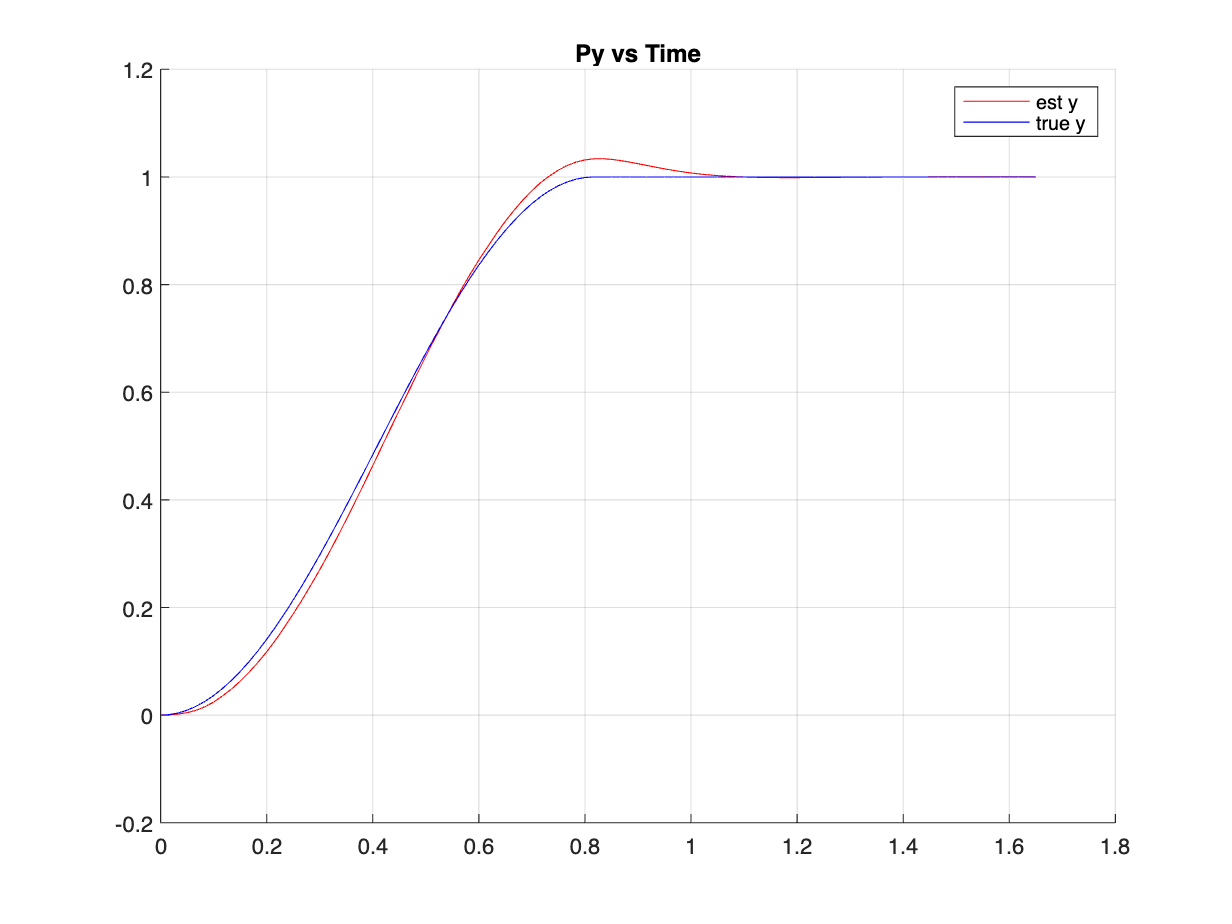

 
figure(1),clf,grid,hold on
plot(dT*dI,y_plot,'r-');
plot(dT*dI,true_position(2,:),'b-');
title('Py vs Time')
axis([0 1.8 -0.2 1.2])
legend('est y','true y')

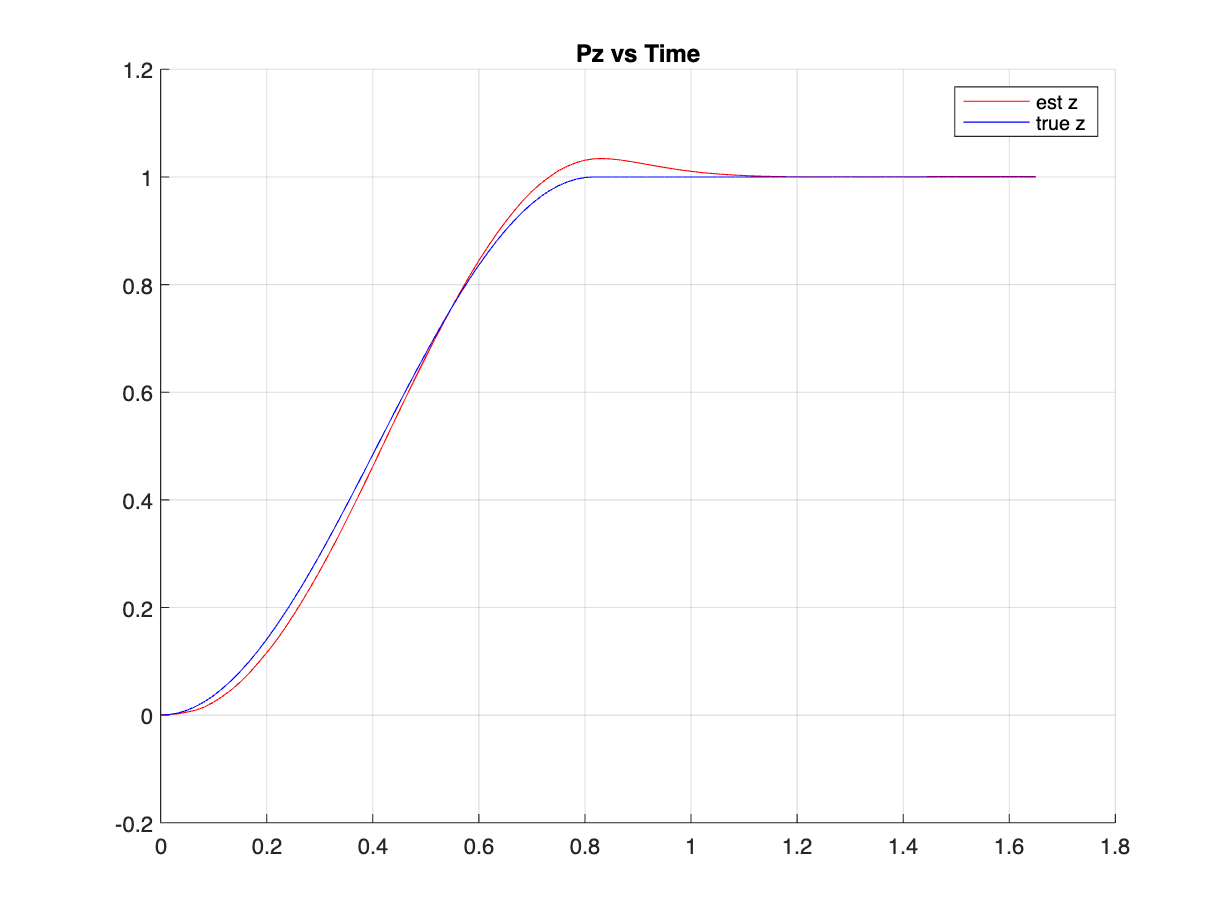

 
figure(1),clf,grid,hold on
plot(dT*dI,z_plot,'r-');
plot(dT*dI,true_position(3,:),'b-');
title('Pz vs Time')
axis([0 1.8 -0.2 1.2])
legend('est z','true z')

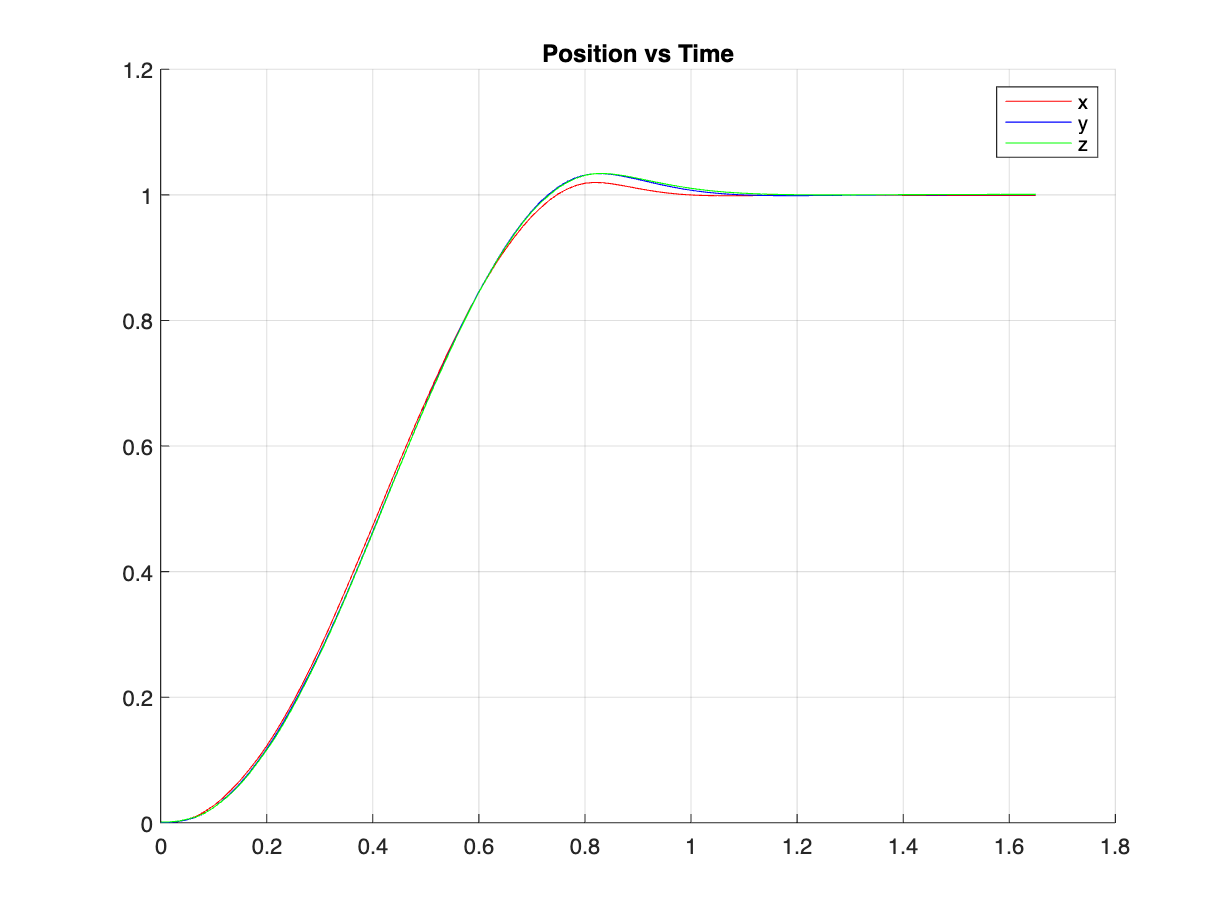


figure(1),clf,grid,hold on
plot(dT*dI,x_plot,'r-');
plot(dT*dI,y_plot,'b-');
plot(dT*dI,z_plot,'g-');
title('Position vs Time')
legend('x','y','z')

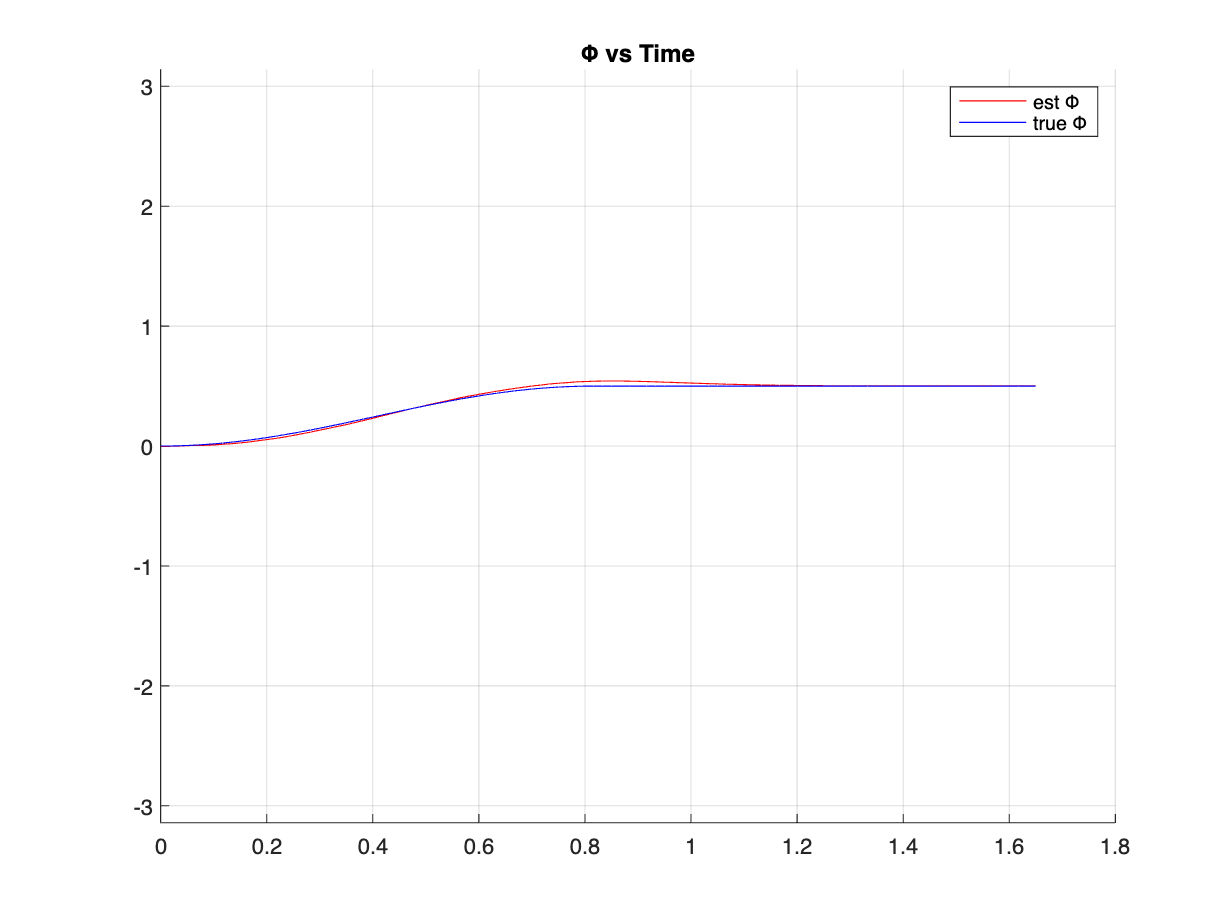


figure(1),clf,grid,hold on
plot(dT*dI,eulx_plot,'r-');
plot(dT*dI,eul_true(1,:),'b-');
title('Φ vs Time')
axis([0 1.8 -pi pi])
legend('est Φ','true Φ')

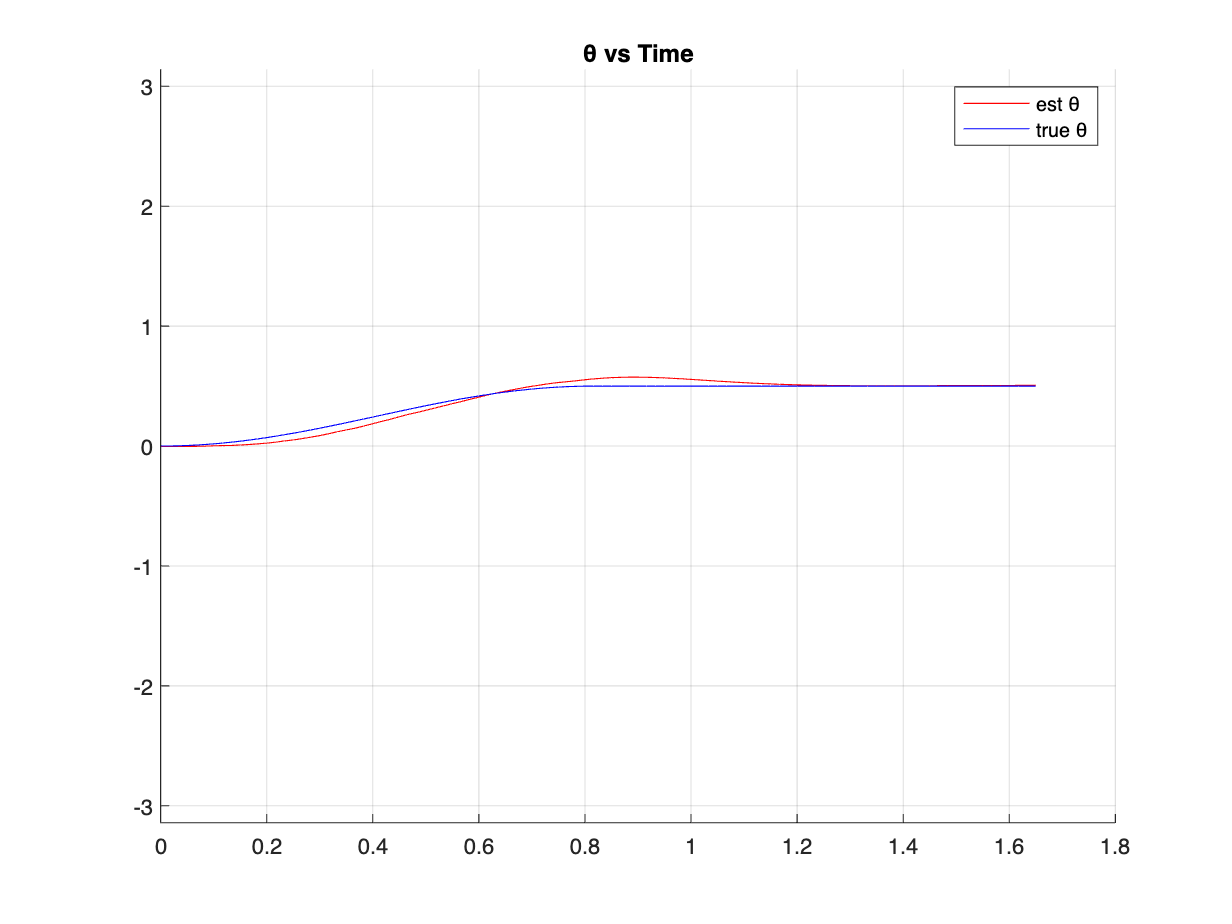

 
figure(1),clf,grid,hold on
plot(dT*dI,euly_plot,'r-');
plot(dT*dI,eul_true(2,:),'b-');
title('θ vs Time')
axis([0 1.8 -pi pi])
legend('est θ','true θ')

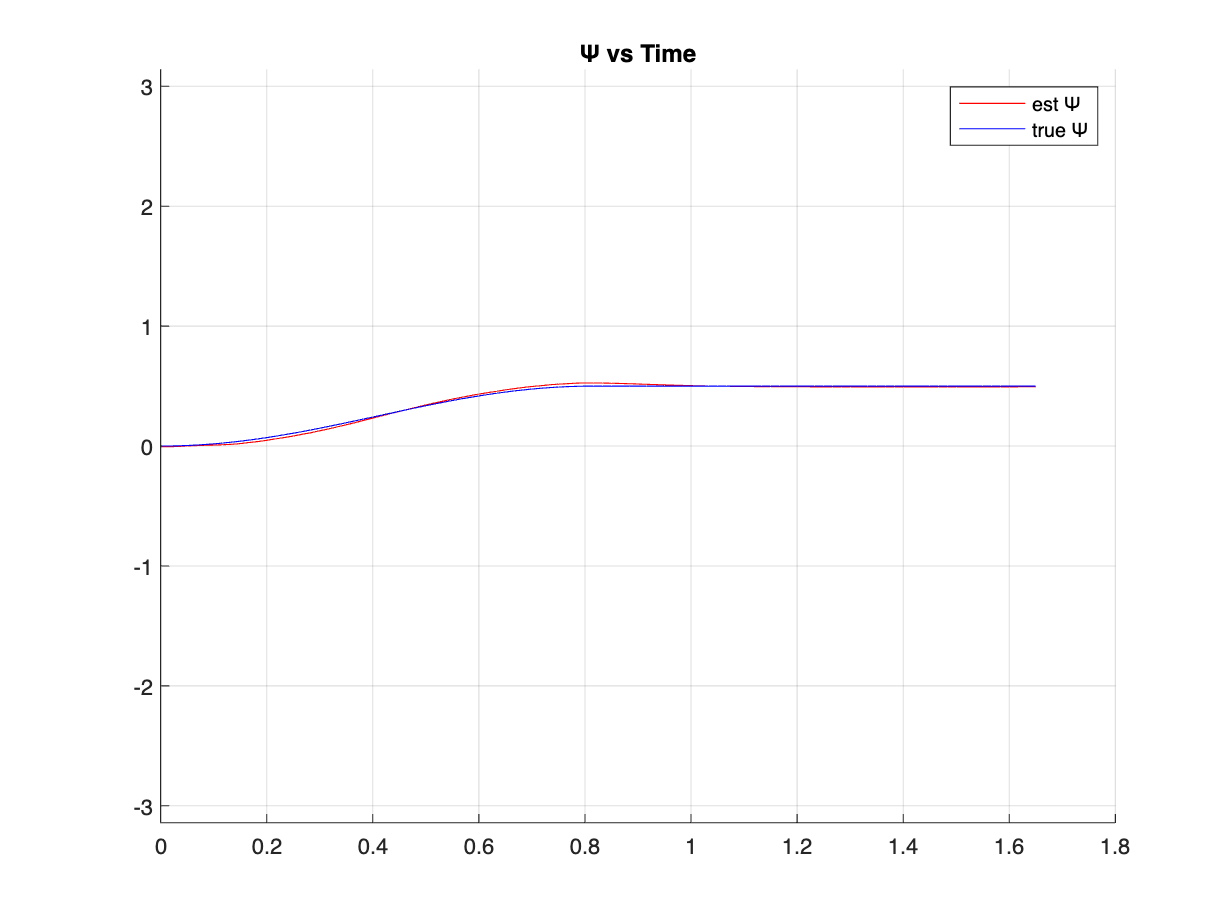

 
figure(1),clf,grid,hold on
plot(dT*dI,eulz_plot,'r-');
plot(dT*dI,eul_true(3,:),'b-');
title('Ψ vs Time')
axis([0 1.8 -pi pi])
legend('est Ψ','true Ψ')

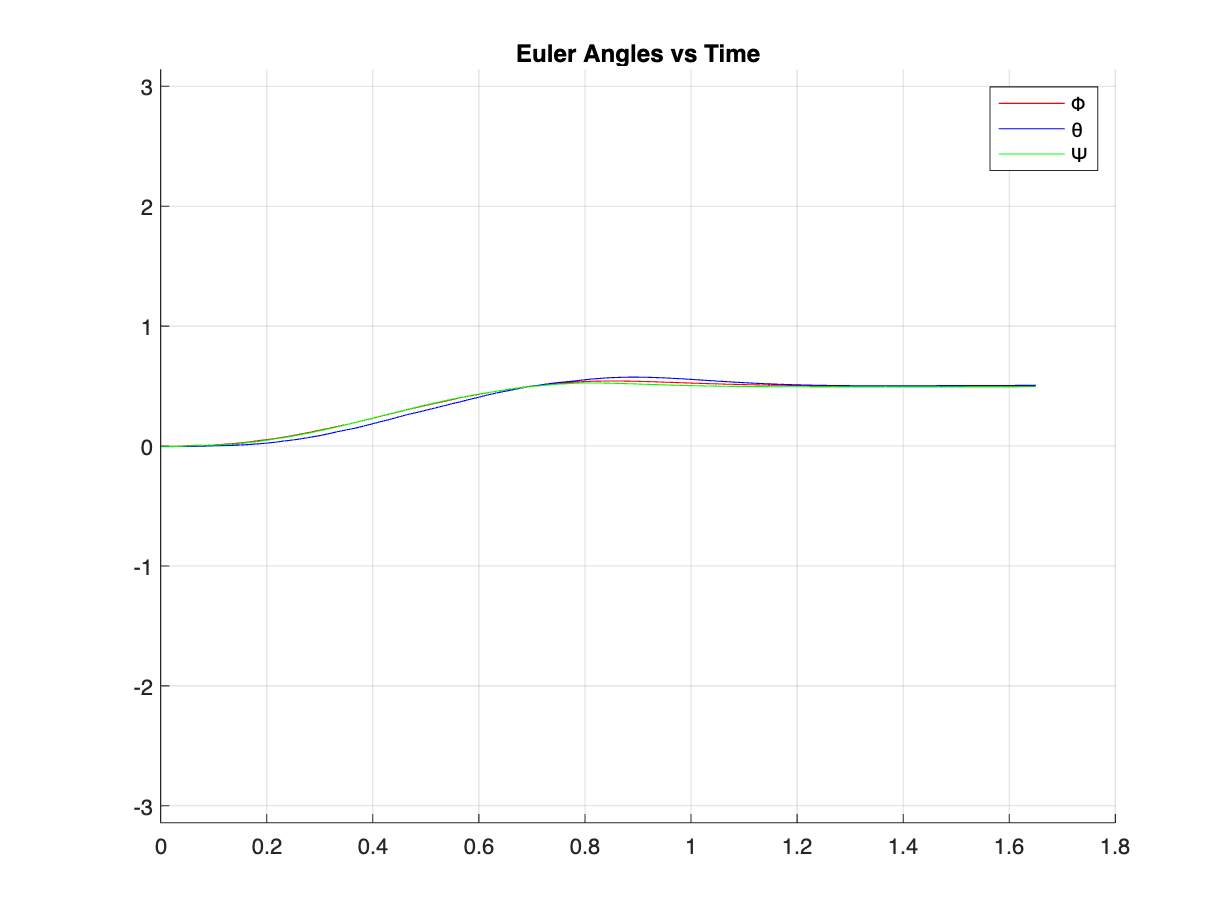


figure(1),clf,grid,hold on
plot(dT*dI,eulx_plot,'r-');
plot(dT*dI,euly_plot,'b-');
plot(dT*dI,eulz_plot,'g-');
axis([0 1.8 -pi pi])
title('Euler Angles vs Time')
 legend('Φ','θ','Ψ')

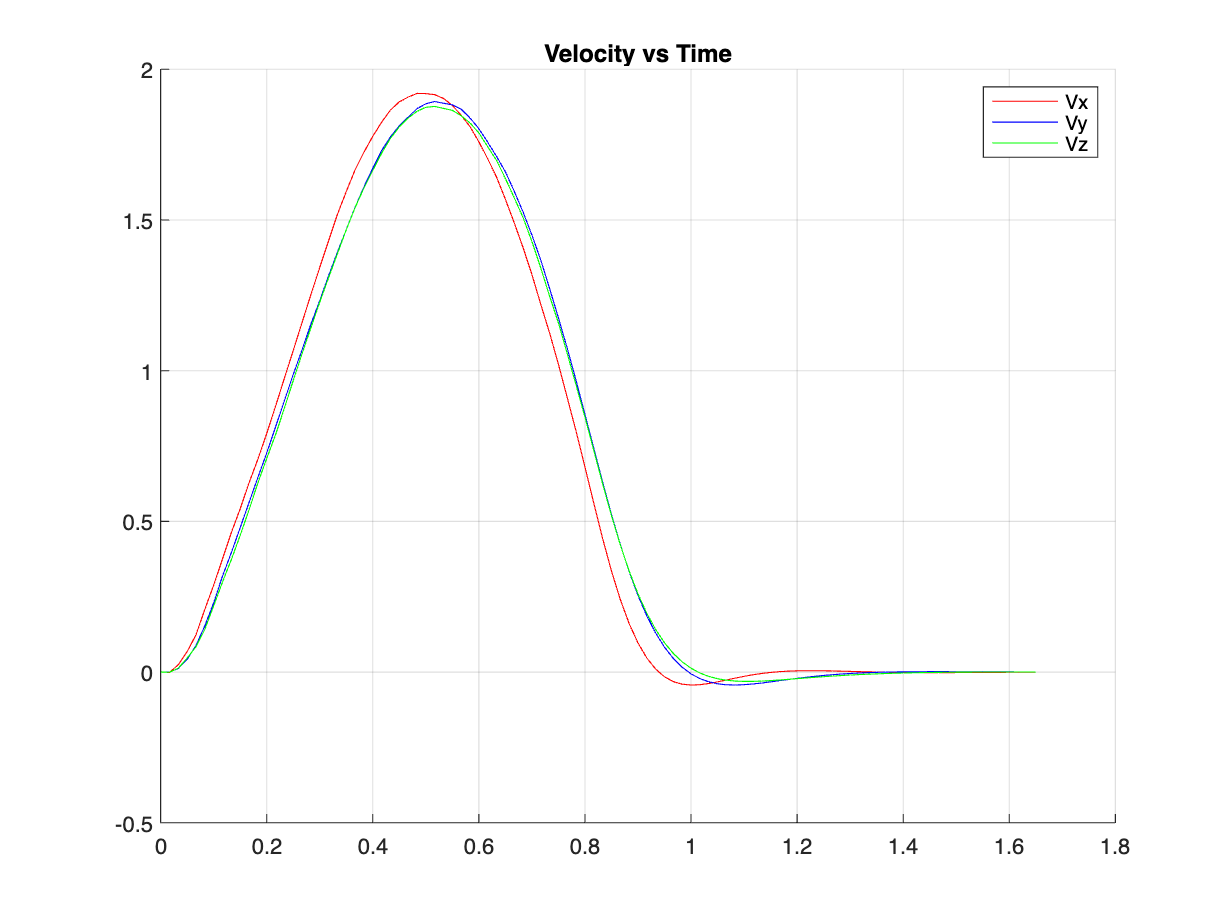


figure(2),clf,grid,hold on
plot(dT*dI,Vx_plot,'r-');
plot(dT*dI,Vy_plot,'b-');
plot(dT*dI,Vz_plot,'g-');
title('Velocity vs Time')
legend('Vx','Vy','Vz')

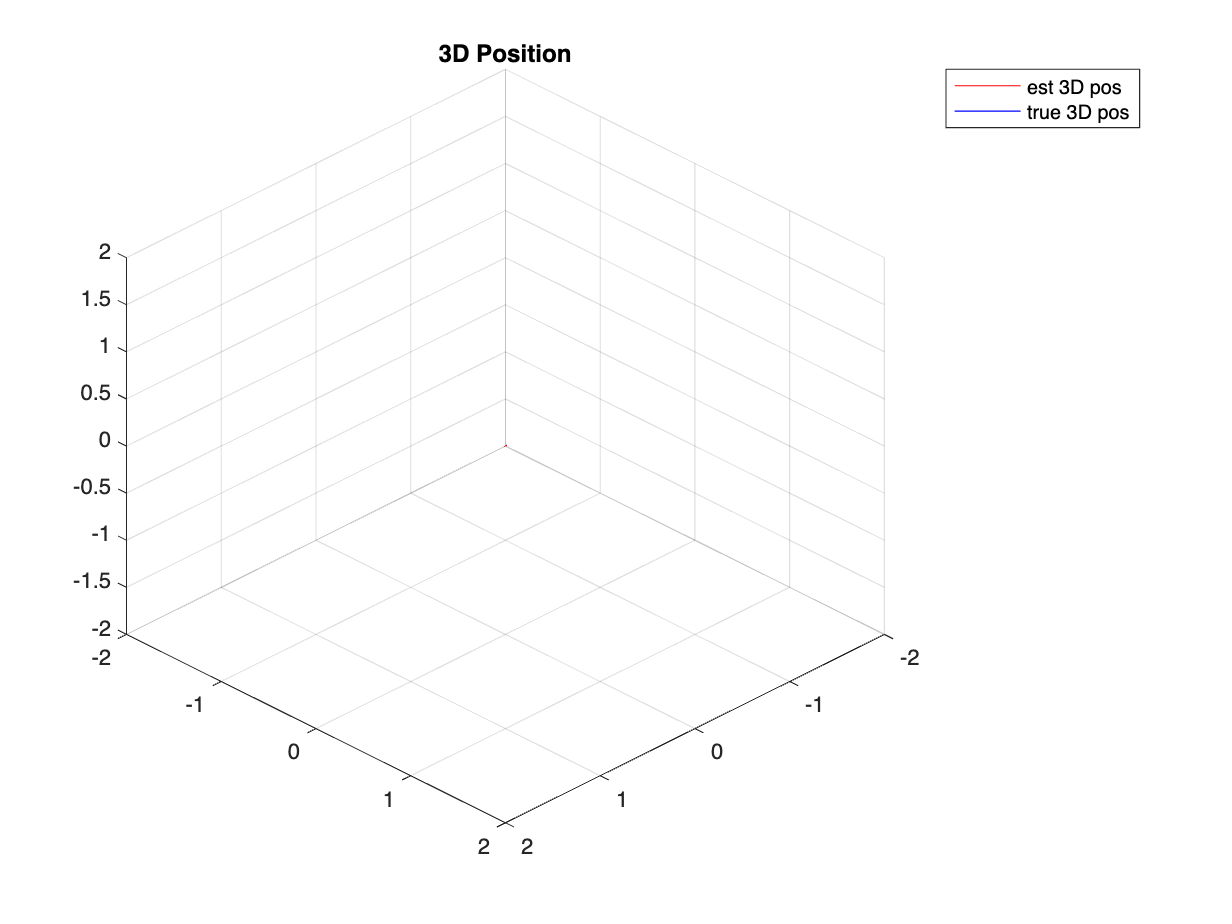


figure(3),clf,grid,hold on
title('3D Position')
axis([-2 2 -2 2 -2 2])
view([2 2 2])
plot3(x_plot,y_plot,z_plot,'r-');
plot3(true_position(1,:),true_position(2,:),true_position(3,:),'b-')
legend('est 3D pos','true 3D pos')

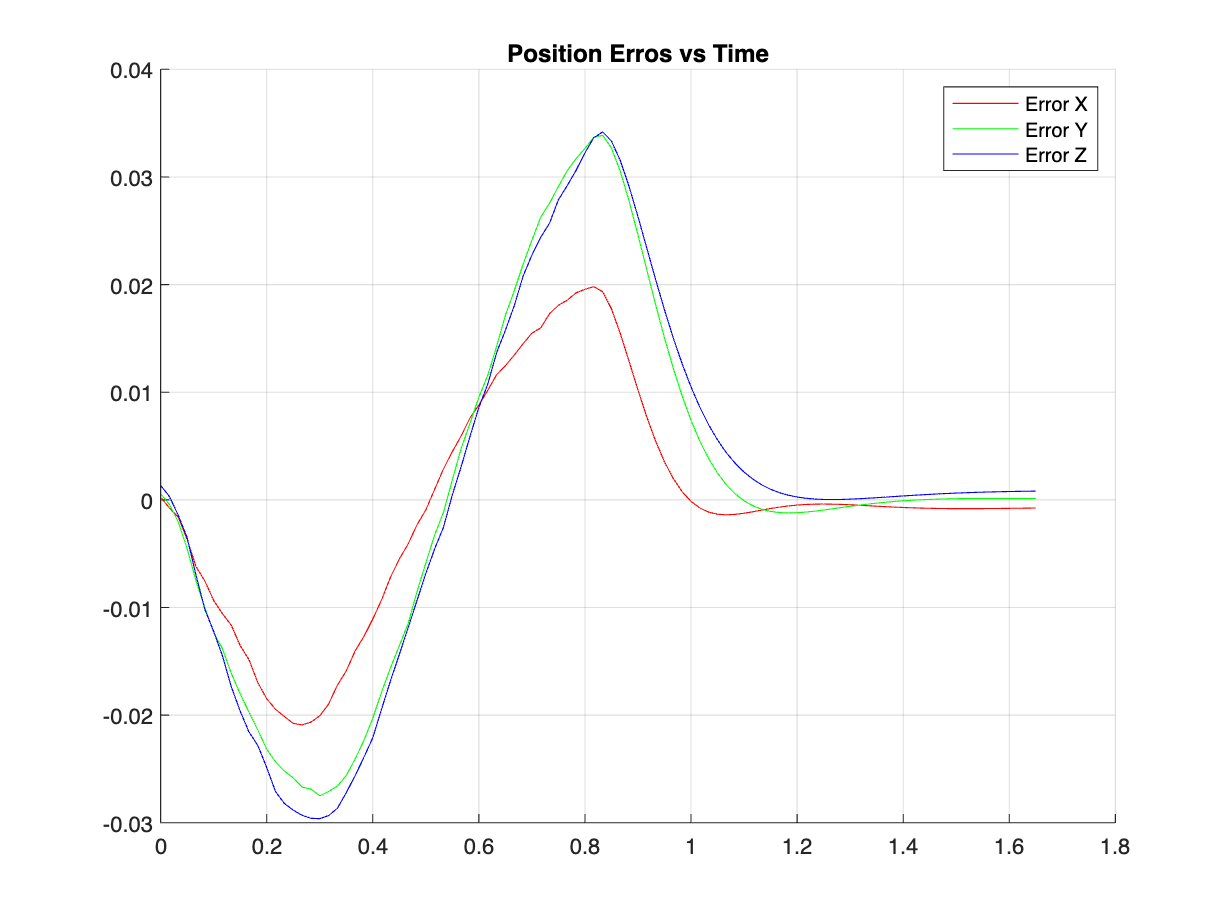


% Error plot:
dI = linspace(0,n_iterations-1,n_iterations);
figure(4),clf,grid,hold on
plot(dT*dI,(x_plot(:) - true_position(1,:)'),'r-');
plot(dT*dI,(y_plot(:) - true_position(2,:)'),'g-');
plot(dT*dI,(z_plot(:) - true_position(3,:)'),'b-');
title('Position Erros vs Time');
legend('Error X','Error Y','Error Z');

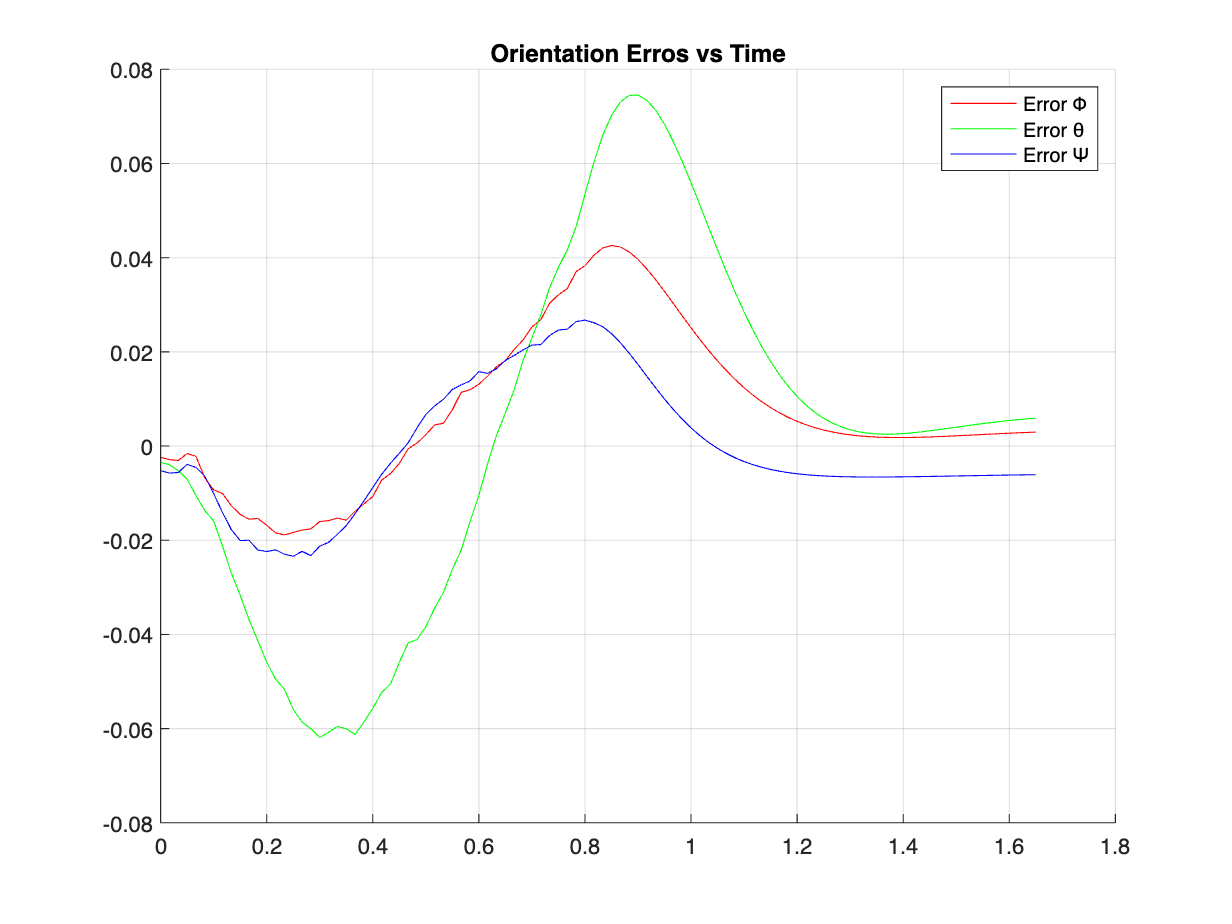


dI = linspace(0,n_iterations-1,n_iterations);
figure(4),clf,grid,hold on
plot(dT*dI,(eulx_plot(:) - eul_true(3,:)'),'r-');
plot(dT*dI,(euly_plot(:) - eul_true(2,:)'),'g-');
plot(dT*dI,(eulz_plot(:) - eul_true(1,:)'),'b-');
title('Orientation Erros vs Time');
legend('Error Φ','Error θ','Error Ψ');


% loc_f1 = zeros(4,50);
% loc_f2 = zeros(4,50);
% loc_f3 = zeros(4,50);
% for k=1:50
%     loc_f1(:,k) = [.25 0 linspace0_1(k) 1]';
%     loc_f2(:,k) = [0 .25 linspace0_1(k) 1]';
%     loc_f3(:,k) = [0 -.25 linspace0_1(k) 1]';
% end
% 
% UV1_1 = C1_*loc_f1;
% for k=1:size(UV1_1,2)
%     UV1_1(:,k) = UV1_1(:,k)/UV1_1(3,k);
% end
% UV1_1=round(UV1_1(1:2,:));
% 
% UV1_2 = C1_*loc_f2;
% for k=1:size(UV1_2,2)
%     UV1_2(:,k) = UV1_2(:,k)/UV1_2(3,k);
% end
% UV1_2=round(UV1_2(1:2,:));
% 
% UV1_3 = C1_*loc_f3;
% for k=1:size(UV1_3,2)
%     UV1_3(:,k) = UV1_3(:,k)/UV1_3(3,k);
% end
% UV1_3=round(UV1_3(1:2,:));
% 
% UV2_1 = C2_*loc_f1;
% for k=1:size(UV2_1,2)
%     UV2_1(:,k) = UV2_1(:,k)/UV2_1(3,k);
% end
% UV2_1=round(UV2_1(1:2,:));
% 
% UV2_2 = C1_*loc_f2;
% for k=1:size(UV2_1,2)
%     UV2_2(:,k) = UV2_2(:,k)/UV2_2(3,k);
% end
% UV2_2=round(UV1_2(1:2,:));
% 
% UV2_3 = C1_*loc_f3;
% for k=1:size(UV2_3,2)
%     UV2_3(:,k) = UV2_3(:,k)/UV2_3(3,k);
% end
% UV2_3=round(UV1_3(1:2,:));

linspace0_1=linspace(0,1,n_uv);
linspace_rest = linspace0_1(n_uv).*ones(1,n_iterations-n_uv);
linspace_all = [linspace0_1 linspace_rest];
quat_true = [1 0 0 0];
true_position = zeros(3,n_iterations);
for k=1:n_iterations
    true_position(:,k) = [0 0 linspace_all(k)]';
end
f1_n = f1.*ones(3,n_iterations);
f2_n = f2.*ones(3,n_iterations);
f3_n = f3.*ones(3,n_iterations);
loc_f1_w = [true_position + quat2rotm(quat_true)*f1_n;ones(1,n_iterations)];
loc_f2_w = [true_position + quat2rotm(quat_true)*f2_n;ones(1,n_iterations)];
loc_f3_w = [true_position + quat2rotm(quat_true)*f3_n;ones(1,n_iterations)];

UVW1_1 = C1_*loc_f1_w;
UVW1_2 = C1_*loc_f2_w;
UVW1_3 = C1_*loc_f3_w;
UVW2_1 = C2_*loc_f1_w;
UVW2_2 = C2_*loc_f2_w;
UVW2_3 = C2_*loc_f3_w;
for k=1:n_iterations
    UVW1_1(:,k) = UVW1_1(:,k)/UVW1_1(3,k);
    UVW1_2(:,k) = UVW1_2(:,k)/UVW1_2(3,k);
    UVW1_3(:,k) = UVW1_3(:,k)/UVW1_3(3,k);
    UVW2_1(:,k) = UVW2_1(:,k)/UVW2_1(3,k);
    UVW2_2(:,k) = UVW2_2(:,k)/UVW2_2(3,k);
    UVW2_3(:,k) = UVW2_3(:,k)/UVW2_3(3,k);
end

UV = round([UVW1_1(1:2,:);UVW1_2(1:2,:);UVW1_3(1:2,:);UVW2_1(1:2,:);UVW2_2(1:2,:);UVW2_3(1:2,:);]);

figure(1),clf,grid,hold on
dI = linspace(0,50-1,50);
x_t = linspace(-pi/2,pi/2,50)

x_t =    -1.5708   -1.5067   -1.4426   -1.3785   -1.3143   -1.2502   -1.1861   -1.1220   -1.0579   -0.9938   -0.9297   -0.8655   -0.8014   -0.7373   -0.6732   -0.6091   -0.5450   -0.4809   -0.4167   -0.3526   -0.2885   -0.2244   -0.1603   -0.0962   -0.0321    0.0321    0.0962    0.1603    0.2244    0.2885    0.3526    0.4167    0.4809    0.5450    0.6091    0.6732    0.7373    0.8014    0.8655    0.9297    0.9938    1.0579    1.1220    1.1861    1.2502    1.3143    1.3785    1.4426    1.5067    1.5708


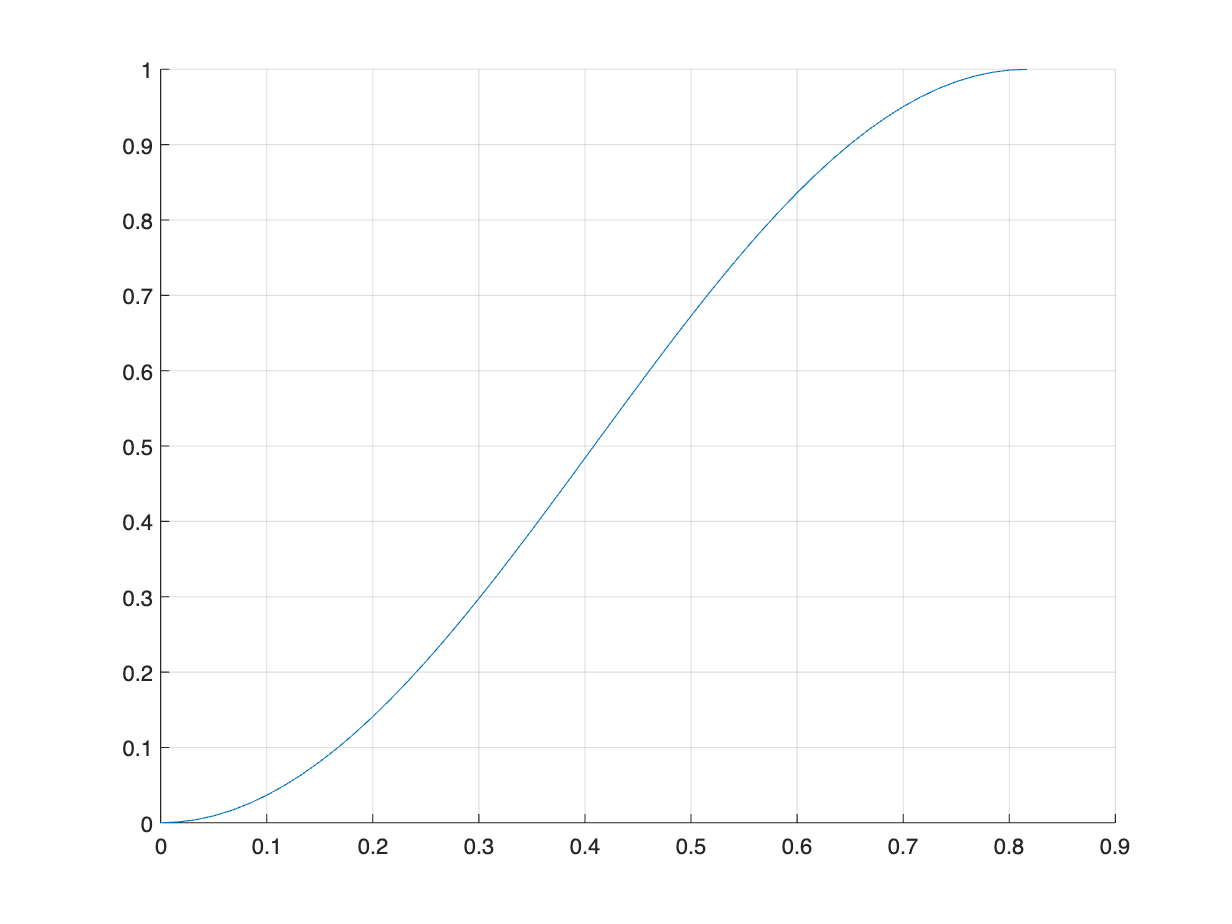

plot(dT*dI,1/2*sin(x_t)+0.5)

phiEUL = linspace(0,2*pi,50)

phiEUL =          0    0.1282    0.2565    0.3847    0.5129    0.6411    0.7694    0.8976    1.0258    1.1541    1.2823    1.4105    1.5387    1.6670    1.7952    1.9234    2.0517    2.1799    2.3081    2.4363    2.5646    2.6928    2.8210    2.9493    3.0775    3.2057    3.3339    3.4622    3.5904    3.7186    3.8468    3.9751    4.1033    4.2315    4.3598    4.4880    4.6162    4.7444    4.8727    5.0009    5.1291    5.2574    5.3856    5.5138    5.6420    5.7703    5.8985    6.0267    6.1550    6.2832



quat_true = zeros(50,4)

quat_true =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


for k=1:50
    quat_true(k,:) = eul2quat([0 0 phiEUL(k)]);
end
quat_true

quat_true =     1.0000         0         0         0
    0.9979    0.0641         0         0
    0.9918    0.1279         0         0
    0.9816    0.1912         0         0
    0.9673    0.2537         0         0
    0.9491    0.3151         0         0
    0.9269    0.3753         0         0
    0.9010    0.4339         0         0
    0.8713    0.4907         0         0
    0.8381    0.5455         0         0


linspace(1,500,500)

ans =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
